clear
close all
hold off


%Desviación estándar es v=2
v=2;
%Desviación en la formación de robots es delta=0.1
delta=0.1;


N=4; %Número de robots (a partir de N=6 buena aproximación)
iteration=200; %Número de iteraciones
step_size=0.1;
D=5; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0_initial=[30;30]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];

w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0_initial;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
simulation=5; %número de simulaciones
mod_rc=zeros(iteration,simulation);
k=1.1;
c1=10^-4;
c2=0.1; %Parámetros para el line search


for ki=1:simulation
    c0=c0_initial;
    for i=1:iteration
        %Aproximación del gradiente en el centro   
        for j=1:100
            grad_centr_est(:,j)=gradient_point2D_ruido(c(:,i),t(i),N,D,S,w0,v,delta);
        end
        media1=mean(grad_centr_est(1,:));
        media2=mean(grad_centr_est(2,:));
        grad_centr(:,i)=[media1;media2];
        %Dirección de descenso
        p(:,i)=-grad_centr(:,i);
        %Aplicación del método del gradiente ascendente
        alpha1=1;
        steplengthParam=[c1,c2,alpha1,k];
        [alpha(i),u(i)]=alpha_strongWolfe_RUIDO(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0,v,delta);
        c(:,i+1)=c(:,i)+alpha(i)*p(:,i);
        
        %Hay un nuevo centro alrededor del cual se tienen que poner los robots
        c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
        mod_r_c(i)=norm(c0-r0);
    end
    mod_rc(:,ki)=mod_r_c;
    num_iteraciones(ki)=sum(u);
end


Representación de la media y la desviación estándar:

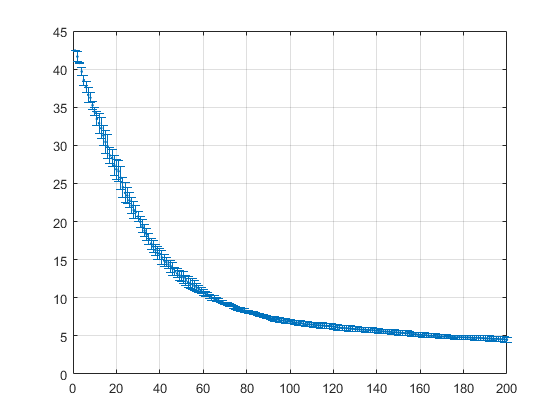

for h=1:iteration
    media(h)=mean(mod_rc(h,:));
    desv_std(h)=std(mod_rc(h,:));
end
errorbar(1:iteration,media,desv_std,'.')
grid on

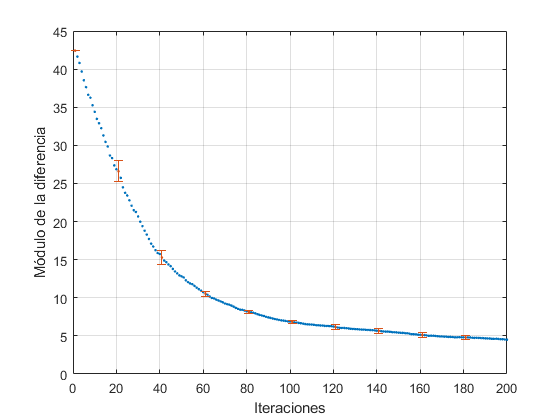


plot(1:iteration,media,'.')
hold on
puntos=1:20:iteration;
errorbar(puntos,media(puntos),desv_std(puntos),'.')
xlabel('Iteraciones')
ylabel('Módulo de la diferencia')
grid on


iteraciones_media=mean(num_iteraciones)

iteraciones_media = 213748